# Get Started with Image Classification

This example shows how to create a simple convolutional neural network for deep learning classification using the Deep Network Designer app. Convolutional neural networks are essential tools for deep learning and are especially suited for image recognition.

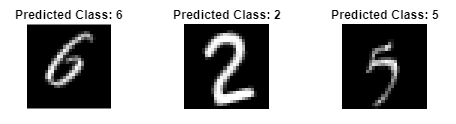

## Load Image Data

Load the digit sample data as an image datastore. To access this data, open the example as a live script. The `imageDatastore` function automatically labels the images based on folder names. The data set has 10 classes and each image in the data set is 28-by-28-by-1 pixels. 

dataFolder = fullfile(toolboxdir('nnet'),'nndemos','nndatasets','DigitDataset');

imds = imageDatastore(dataFolder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

classNames = categories(imds.Labels);

Partition the data into training, validation, and test data sets. Use 70% of the images for training, 15% for validation, and 15% for testing. Specify `"randomized"` to assign the specified proportion of files from each class to the new data sets. The `splitEachLabel` function splits the image datastore into three new datastores.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,0.15,"randomized");

## Define Network Architecture

To build the network, use the Deep Network Designer app. 

deepNetworkDesigner

To create a blank network, pause on **Blank Network** and click **New**. 

In the **Designer** pane, define the convolutional neural network architecture. Drag layers from the **Layer Library** and connect them. To quickly search for layers, use the **Filter layers** search box in the **Layer Library** pane. To edit the properties of a layer, click the layer and edit the values in the **Properties** pane.

Drag these layers in order and connect them sequentially. First, drag an **imageInputLayer** onto the canvas and set **InputSize** to `28,28,1`.

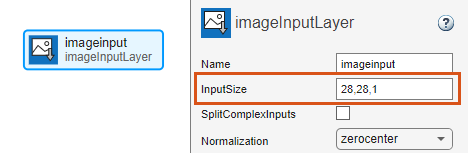

Next, drag these layers onto the canvas and connect them in order: 

- **convolution2dLayer**

- **batchNormalizationLayer**

- **reluLayer**

Then, connect a **fullyConnectedLayer** and set **OutputSize** to the number of classes in the data, in this example, 10.

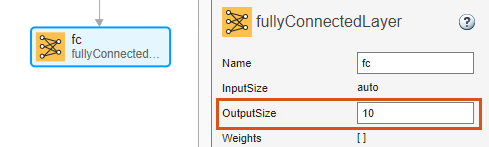

Finally, add a **softmaxLayer**.

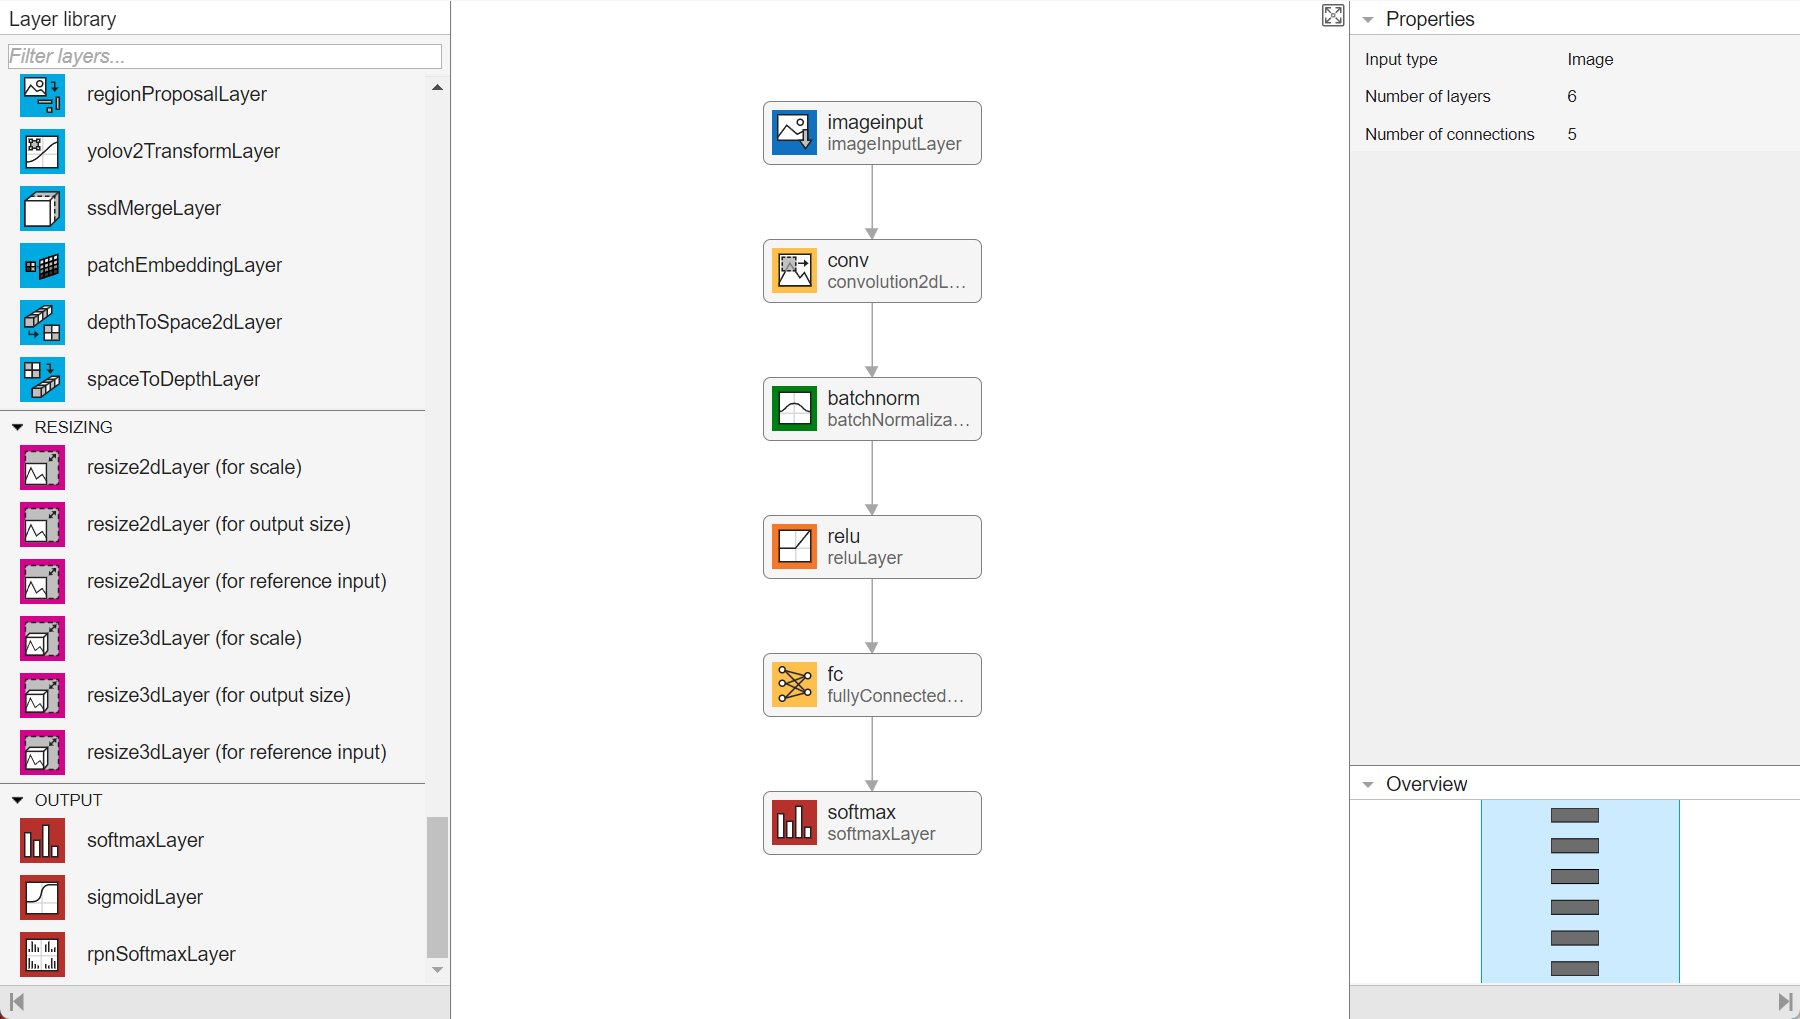

To check that the network is ready for training, click **Analyze**. The Deep Learning Network Analyzer reports zero errors or warnings, so the network is ready for training. To export the network, click **Export**. The app saves the network as the variable `net_1`.

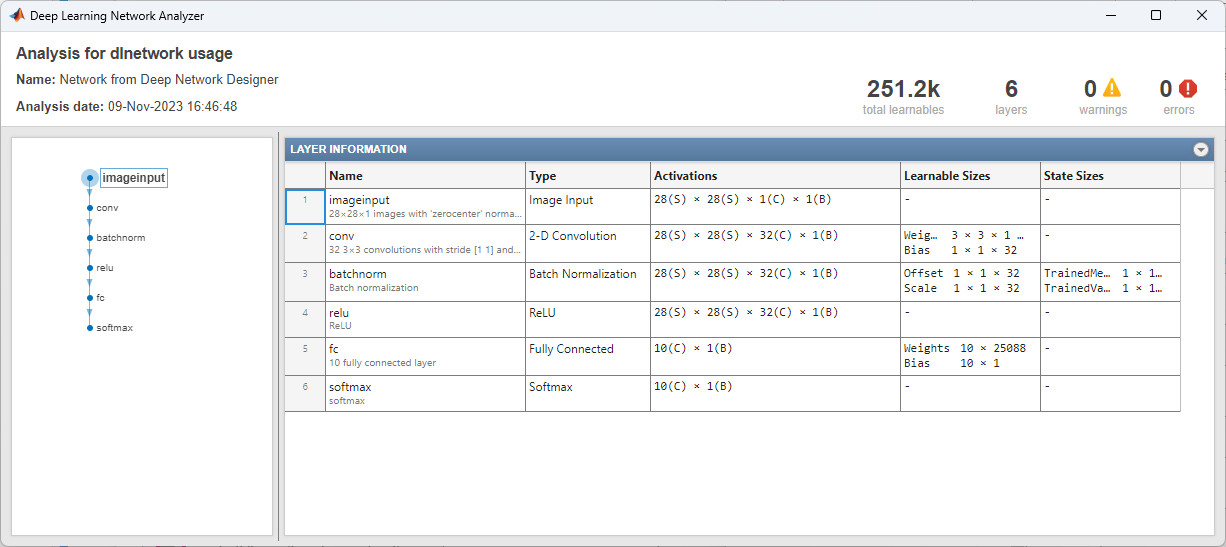

## Create Architecture without DND

net_1 = [...
    imageInputLayer([28 28 1]), ...
    convolution2dLayer(3, 32), ...
    reluLayer, ...
    fullyConnectedLayer(10), ...
    softmaxLayer];

## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    InitialLearnRate = 0.01);

## **Train Neural Network**

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. Because the aim is classification, use cross-entropy loss.

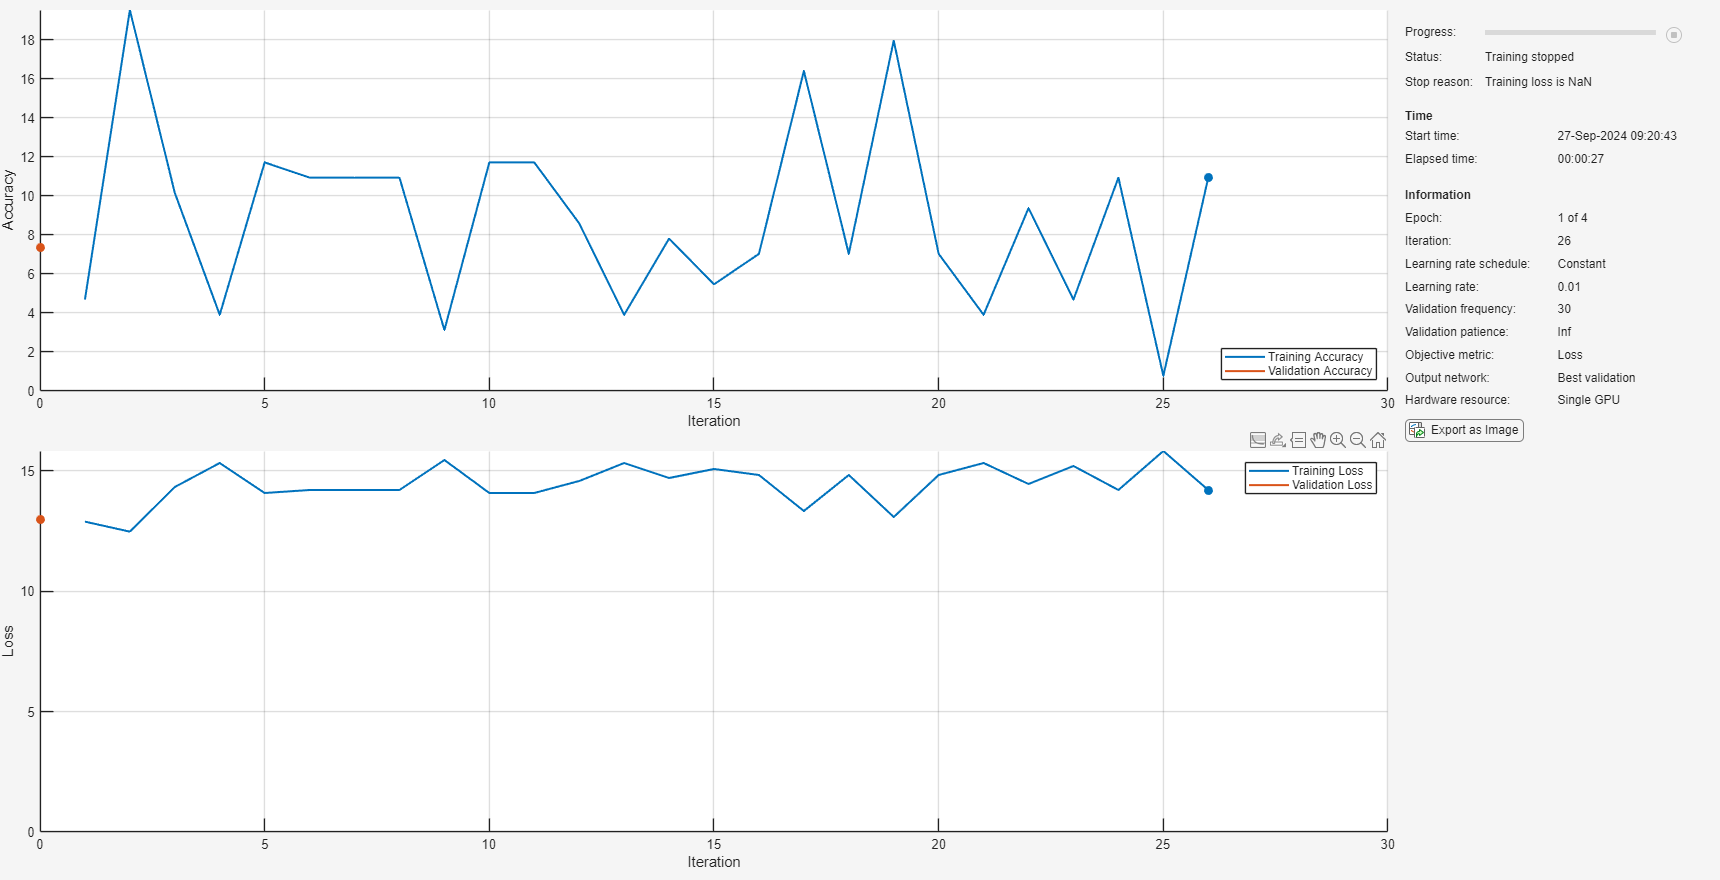

net = trainnet(imdsTrain,net_1,"crossentropy",options);

## Test Neural Network

Test the neural network using the [`testnet`](docid:nnet_ref.mw_3eb84788-36da-4e3e-a351-ecbc55b86c2b) function. For single-label classification, evaluate the accuracy. The accuracy is the percentage of correct predictions. By default, the `testnet` function uses a GPU if one is available. To select the execution environment manually, use the `ExecutionEnvironment` argument of the `testnet` function.

accuracy = testnet(net,imdsTest,"accuracy")

accuracy = 8

## Fine Tuning 1: Change Learning Rate and Train

The network we train tries to minimize a loss function by using an algorithm called gradient descent. The learning rate contributes to whether we can minimize that function.

- Too high - the loss function never converges to a minimum. This is what happened when we used the default learning rate.

- Too low - the loss function converges on a local minima.

Change the learning rate above by selecting a different value from the drop down menu. Observe the change in the accuracy

## Fine Tuning 2: Improve Network Architecture and Train

Improving the network architecture can increase training accuracy. This time, we will try a more sophisticated network architecture. This network has multiple convolution layers, as well as [batch normalization](matlab:doc batchNormalizationLayer) layers, which improve the quality and convergence rate of the training.

net_2 = [
    imageInputLayer([28 28 1])    
    
    convolution2dLayer(3, 32)
    batchNormalizationLayer
    reluLayer    
    maxPooling2dLayer(5)
    
    convolution2dLayer(3, 64)    
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(5)
    
    fullyConnectedLayer(10)
    softmaxLayer];

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false, ...
    InitialLearnRate = 0.0001);

netnew = trainnet(imdsTrain, net_2, "crossentropy", options);

accuracy = testnet(netnew,imdsTest,"accuracy")

accuracy = 44.4000

## Food for thought

Changing the network architecture definetly had an impact of the accuracy but at the same time size of the network increased signigicants. Is the improvement worth the increase in size?

## Make Predictions

Make predictions using the [`minibatchpredict`](docid:nnet_ref.mw_c7ae5ad7-5485-4270-8657-694ab264fb57) function and convert the scores to labels using the [`scores2label`](docid:nnet_ref.mw_b4669b80-206b-472f-a9eb-7e9642b3c38c) function. By default, the `minibatchpredict` function uses a GPU if one is available.

scores = minibatchpredict(net,imdsTest);
YTest = scores2label(scores,classNames);

Visualize some of the predictions.

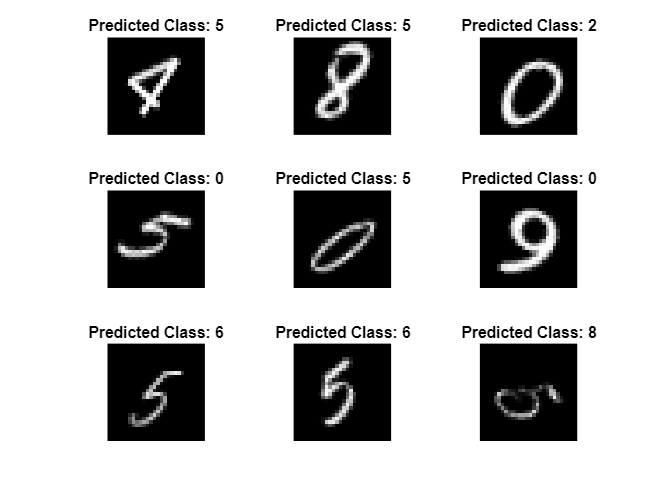

numTestObservations = numel(imdsTest.Files);
idx = randi(numTestObservations,9,1);

figure
tiledlayout("flow")
for i = 1:9
    nexttile
    img = readimage(imdsTest,idx(i));
    imshow(img)
    title("Predicted Class: " + string(YTest(idx(i))))
end

For next steps in deep learning, you can try using pretrained networks and transfer learning. For an example, see [Get Started with Transfer Learning](docid:nnet_gs#mw_e7f28092-4f41-4d94-9820-daffd2145d72).

*Copyright 2020-2024 The MathWorks, Inc.*